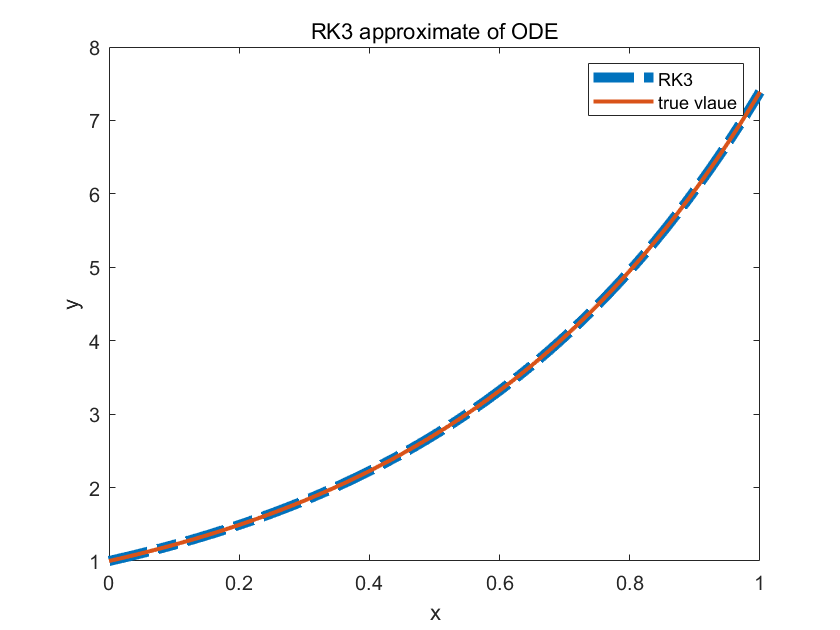

clear
xn=0;
yn=1;
h=0.001;
x=0:h:1;
l=length(x);
y(1)=yn;
yt=exp(2*x);
for i=1:l
    K1=fxy(x(i),y(i));
    K2=fxy(x(i)+h/2,y(i)+h/2*K1);    
    K3=fxy(x(i)+h/2,y(i)+h/2*K2);
    K4=fxy(x(i)+h,y(i)+h*K3);
    y(i+1)=y(i)+h/6*(K1+2*K2+2*K3+K4);
end

y=y(1:l);
plot(x,y,'-.','LineWidth',5)
hold on
plot(x,yt,'-','LineWidth',2)
legend('RK3','true vlaue')
ylabel('y');xlabel('x');
title('RK3 approximate of ODE')
hold off


sum(abs(yt(:)-y(:)))

ans = 5.5915e-10

function [f]=fxy(x,y)
    f=2*y;
end